clear;
clc;
clear all;
close all;
data="Hello, This is my first message over this communication simulation! I am Rishi Gupta"

data = "Hello, This is my first message over this communication simulation! I am Rishi Gupta"

databits=stringToBinary(data)                                      %data converted to ASCII 8 bits

databits =      0     1     0     0     1     0     0     0     0     1     1     0     0     1     0     1     0     1     1     0     1     1     0     0     0     1     1     0     1     1     0     0     0     1     1     0     1     1     1     1     0     0     1     0     1     1     0     0     0     0


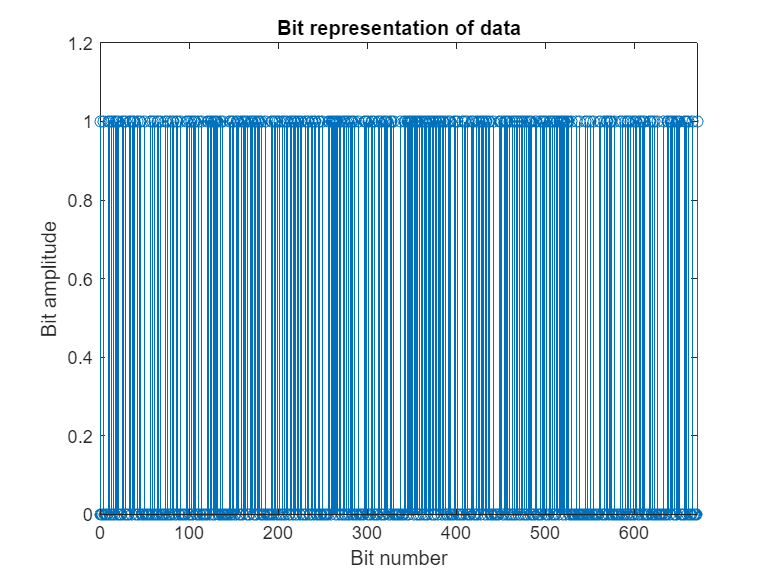

N=length(databits);                                                %length of data bits
tbits=0:N-1;
figure;
stem(tbits,databits);                                              %bits plot
axis([0 inf 0 1.2]);
xlabel("Bit number");
ylabel("Bit amplitude");
title("Bit representation of data");

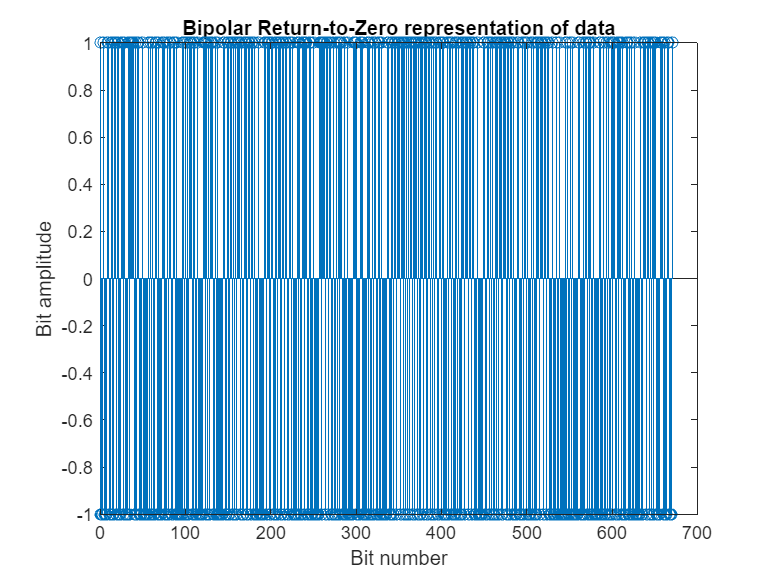

% Bipolar Return-to-Zero (BRC) Mapping
data_signal=zeros(1,N);
data_signal(databits == 1) = 1; 
data_signal(databits == 0) = -1;
figure;
stem(tbits,data_signal);                                           %BRC plot
xlabel("Bit number");
ylabel("Bit amplitude");
title("Bipolar Return-to-Zero representation of data");

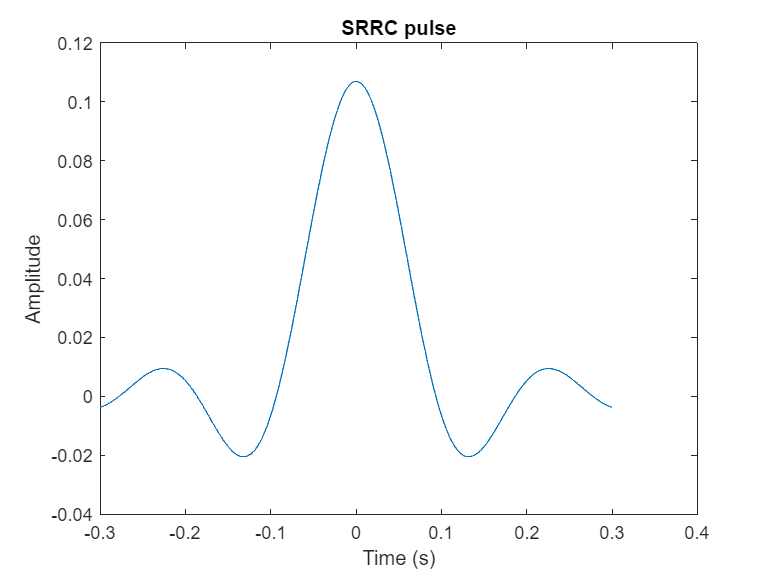

Tb=0.1;                                                            %bit duration in seconds
fs = 1000;                                                         % Sampling frequency (samples per second)
Ts = 1/fs;                                                         % Sampling interval
rolloff = 0.25;                                                    % Roll-off factor
span = 6;                                                          % Span of the pulse in terms of Tb
sps = fs * Tb;                                                     % Samples per symbol (Tb duration)
% Generate the SRRC pulse shape
t = (-span/2 : 1/sps : span/2) * Tb;                               % Time vector of SRRC pluse
pulse = rcosdesign(rolloff, span, sps,'sqrt');                     % SRRC pulse
plot(t,pulse);
xlabel('Time (s)');
ylabel('Amplitude');
title('SRRC pulse');

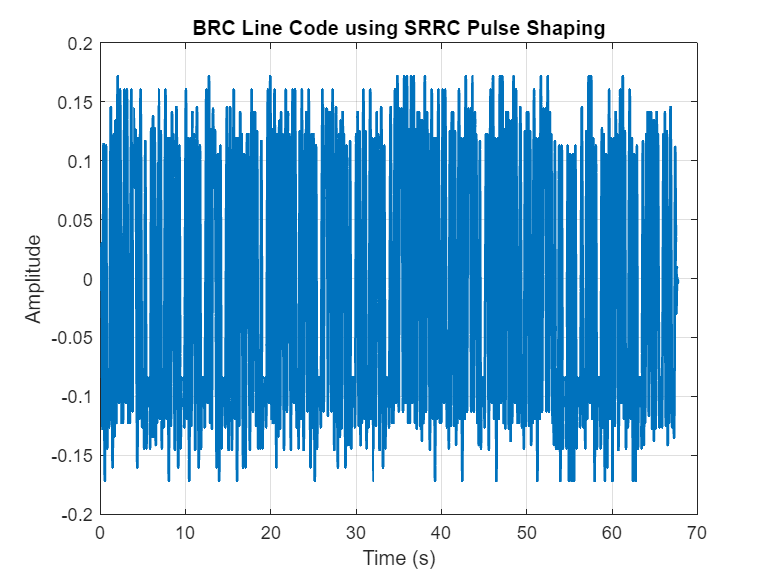

% Upsample and filter the signal
data_upsampled = upsample(data_signal, sps);                       % Insert zeros between symbols
pulse_signal = conv(data_upsampled, pulse);                        % Pulse sampling-SRRC filtering
% Time vector for the shaped signal
t_brc = (0:length(pulse_signal)-1) * Ts; 

% Plot the generated BRC signal
figure;
plot(t_brc, pulse_signal, 'LineWidth', 1.5)
xlabel('Time (s)');
ylabel('Amplitude');
title('BRC Line Code using SRRC Pulse Shaping');
grid on;

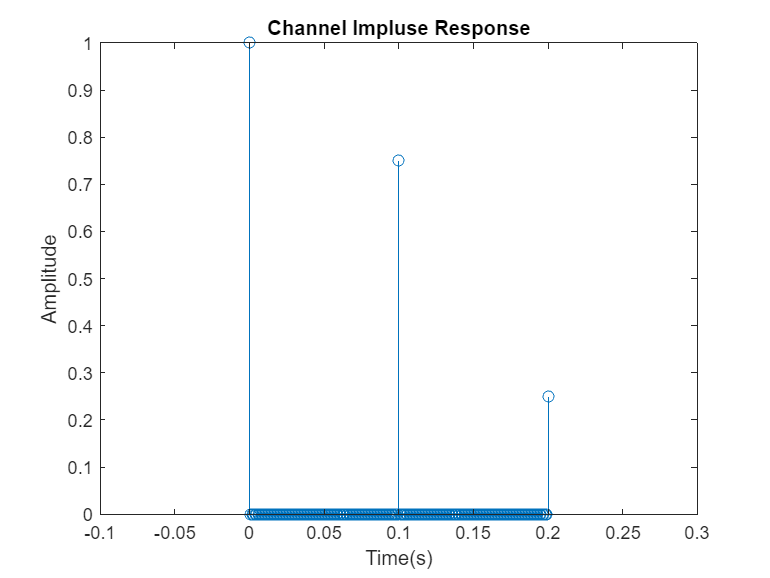

% Define the channel impulse response
h = zeros(1, 2 * sps + 1);
h(1) = 1;                                                          % δ(t)
h(sps + 1) = 0.75;                                                 % 0.75δ(t - Tb)
h(2 * sps + 1) = 0.25;                                             % 0.25δ(t - 2Tb)
t_channel=0:1/(sps/Tb):0.2;                                        %Time vector for channel
%plotting channel impusle response
stem(t_channel,h)
xlabel("Time(s)");
ylabel("Amplitude");
title("Channel Impluse Response");
xlim([-0.1 0.3]);

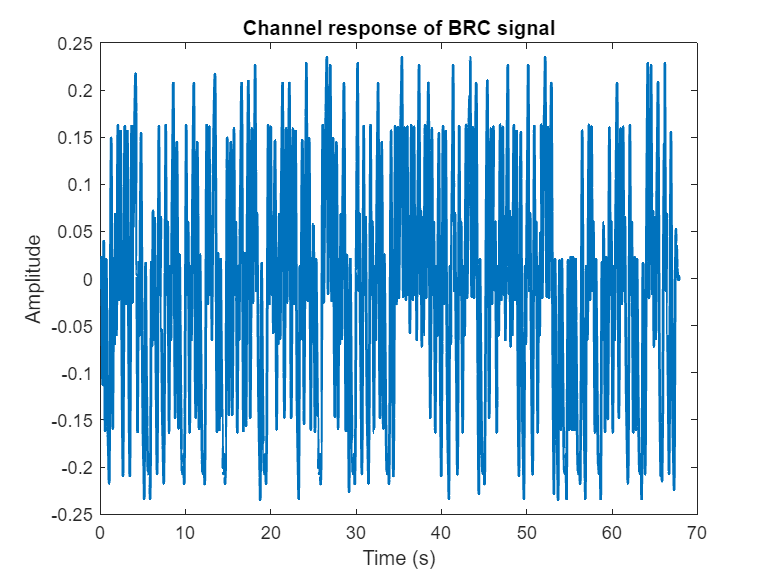

channel_response=conv(pulse_signal,h);                             %Channel output
t_channel = (0:length(channel_response)-1) * Ts;                   %Time vector for channel response 
% Plot the channel BRC signal output
plot(t_channel, channel_response, 'LineWidth', 1.5)
xlabel('Time (s)');
ylabel('Amplitude');
title('Channel response of BRC signal');

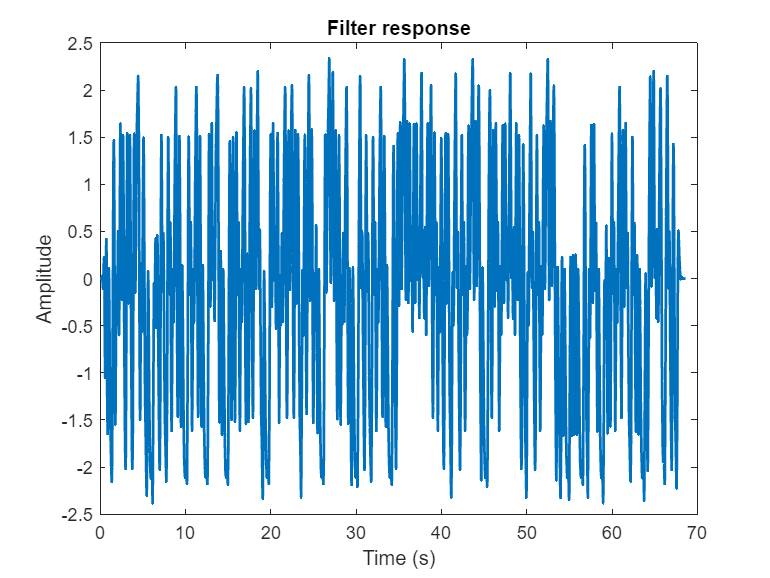

rxfilter_response = conv(channel_response, pulse);                  % SRRC filtering at receiver
t_rxfilter = (0:length(rxfilter_response)-1) * Ts;                 %Time vector for received filter output
% Plot the received BRC signal
plot(t_rxfilter, rxfilter_response, 'LineWidth', 1.5)
xlabel('Time (s)');
ylabel('Amplitude');
title('Filter response');

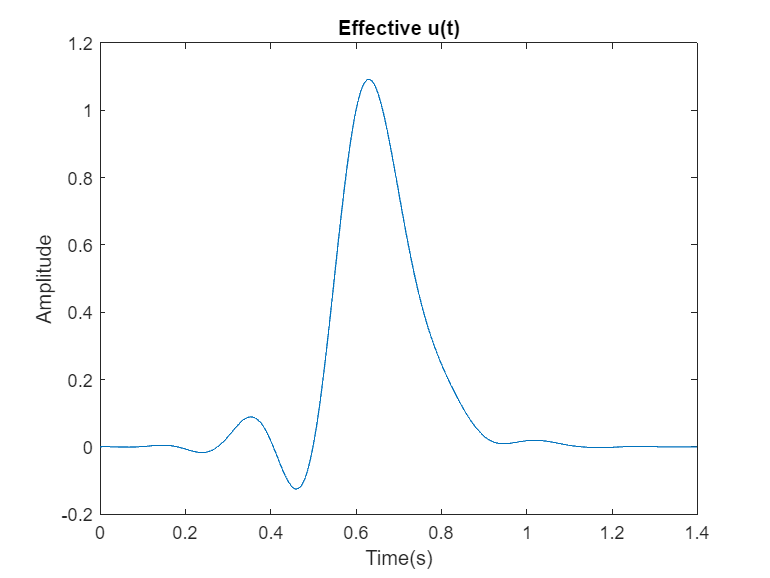

effective_u=conv(pulse,conv(pulse,h));
sampled_effective_u=effective_u(1:100:end);
t_effective_u = (0:length(effective_u)-1) * Ts;
figure;
plot(t_effective_u,effective_u);
xlabel("Time(s)");
ylabel("Amplitude");
title("Effective u(t)");

fid = fopen("sampled_effective_u.txt", "w");
if fid == -1
    error('Failed to open file!');
end
fprintf(fid, '%f\n', sampled_effective_u);
fclose(fid);
fid = fopen("rxfilter_response.txt", "w");
if fid == -1
    error('Failed to open file!');
end
fprintf(fid, '%f\n', rxfilter_response);
fclose(fid);
rxdata_samples=rxfilter_response(601:100:end-800);                  %sampling the filtered signal
rxdata_bits=rxdata_samples>0;                                       %decision maker for bitss
 

stringDataBeforeEqualizer=binaryToAsciiString(rxdata_bits)

stringDataBeforeEqualizer = '@%llo¬ □h){ ){ /} #iz{ô /e{ûawå /ÿ%x 4h){ #□ïo}□ic`ti□ÿ ;io}l ti□ÿ  	 !m □i{h) □ýp4 '

clear;

fid = fopen('equalizer_response.txt', 'r');
if fid == -1
    error('Failed to open file.');
end

equalizer_response = fscanf(fid, '%f');                            % Reads all doubles into a column vector
fclose(fid);
equalizer_response=equalizer_response';
rxdata_samples=equalizer_response(601:100:end-1200);                 %sampling the filtered signal
rxdata_bits=rxdata_samples>0;                                       %decision maker for bitss
 

stringDataAfterEqualizer=binaryToAsciiString(rxdata_bits)

stringDataAfterEqualizer = 'Hello, This is my first message over this communication simulation! I am Rishi Gupta'

function binaryMatrix = stringToBinary(sentence)
% STRINGTOBINARY Converts text input to 8-bit binary ASCII matrix
% Handles both character arrays and string objects

% Convert string type to character array if necessary
if isstring(sentence)
    sentence = char(sentence);
end
% Convert to ASCII values (now guaranteed to work)
asciiValues = double(sentence);

% Convert to 8-bit binary matrix
binaryMatrix = dec2bin(asciiValues, 8)-'0';
%convert to binary row matrix
binaryMatrix=reshape(binaryMatrix.', 1, []);
end



function originalString = binaryToAsciiString(binaryInput)
% BINARYTOASCIISTRING Converts binary row vector back to original string
%   Input: Binary vector (0s and 1s) or binary string
%   Output: Reconstructed string

% Handle different input types
if ischar(binaryInput) || isstring(binaryInput)
    % Convert string input to numeric vector
    binaryInput = char(binaryInput);
    binaryInput = double(binaryInput == '1');
end

% Reshape to (N x 8) matrix (each row = 1 character)
binaryMatrix = reshape(binaryInput, 8, [])';

% Convert binary to decimal ASCII codes
asciiCodes = bin2dec(char(binaryMatrix + '0')); % Convert to '0'/'1' characters

% Convert ASCII codes to characters
originalString = char(asciiCodes)';

end